clear
clf
%3rd problem (a)

a = 1.115 * 10^-3; %Thermal diffusivity(m^2/s)
x = linspace(-pi,pi,1000);
t = 0;
u = cos(x).*exp(-a*t);

t_1 = 50;
u_1 = cos(x).*exp(-a*t_1);

t_2 = 100;
u_2 = cos(x).*exp(-a*t_2);

t_3 = 1000;
u_3 = cos(x).*exp(-a*t_3);

t_4 = 10000;
u_4 = cos(x).*exp(-a*t_4);

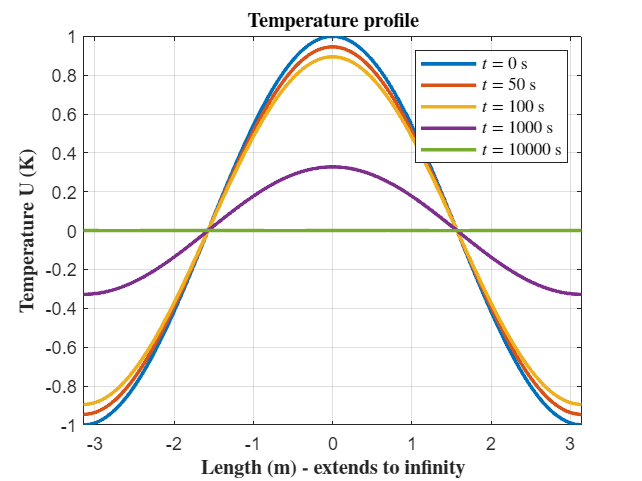

%Plots
h1 = plot(x, u,'LineWidth', 2);
grid on
ylabel('$\textbf{Temperature U (K)}$','Interpreter', 'latex')
xlabel('$\textbf{Length (m) - extends to infinity}$', 'Interpreter', 'latex')
title('$\textbf{Temperature profile}$', 'Interpreter', 'latex');
hold on
h2 = plot(x, u_1,'LineWidth', 2);
h3 = plot(x, u_2,'LineWidth', 2);
h4 = plot(x, u_3,'LineWidth', 2);
h5 = plot(x, u_4,'LineWidth', 2);
xlim([-pi pi])
legend([h1, h2, h3, h4, h5], '$t = 0$ s', '$t = 50$ s', '$t = 100$ s', '$t = 1000$ s', '$t = 10000$ s', 'Interpreter', 'latex');

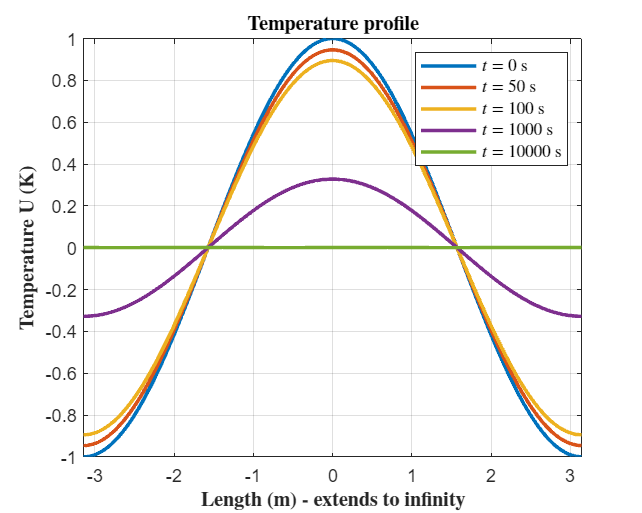

%Saving plot

outputFileName = 'Problem_3_a.png';
figureHandle = gcf;
figureWidth = 1000; % in pixels
figureHeight = 800; % in pixels
set(figureHandle, 'Position', [100, 100, figureWidth, figureHeight]); 
print(figureHandle, outputFileName, '-dpng', '-r600');